# Fitting 1st Order Poles

We want to be able to idenitfy an unknown system from its time response.  To demonstrate this here is some data from the step response of some system.

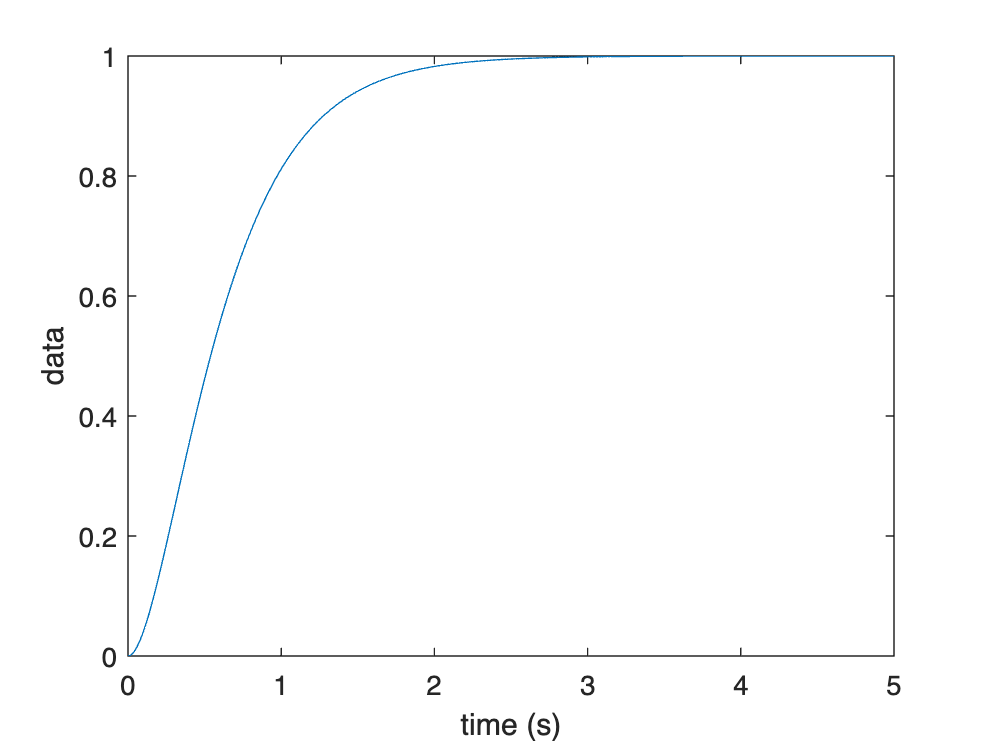

load data1.mat
plot(t,y)
xlabel('time (s)')
ylabel('data')

The response does not have oscillations, so we might assume first-order poles.  For now we will assume the system has two poles:$-\sigma_1, -\sigma_2$, and that


$$\sigma_1 < \sigma_2$$


We could add more terms, but the approach used here does not work well for more than two poles.

The response then looks like this.


$$y(t) = 1 + A_1 e^{-\sigma_1 t} + A_2 e^{-\sigma_2 t}$$


which has three parts:

    response = constant + slow term + fast term

The constant part is easy.  The fast term decays quickly, so after a long time (more than several fast time constants) the fast term looks like this.


$$A_1 e^{-\sigma_1 t} = y(t) - 1$$


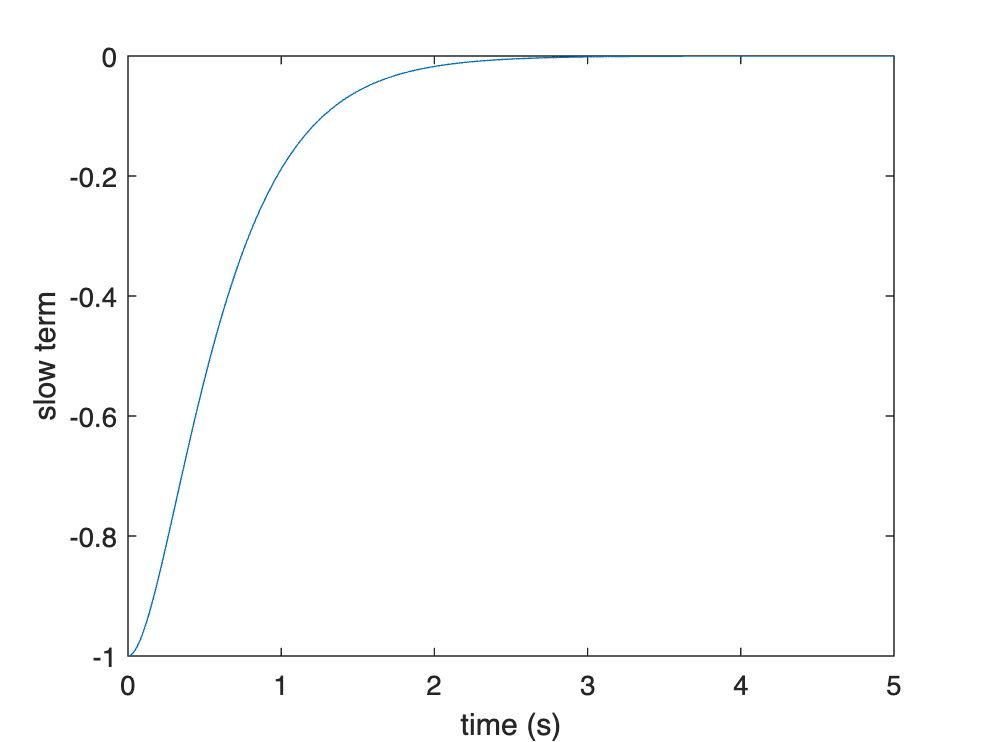

slow_term = y-1;
plot(t,slow_term)
xlabel('time (s)')
ylabel('slow term')

This term is negative, so we know that $A_1$is negative.  If we plot the log of this we get


$$\ln | A_1 | - \sigma_1 t$$


which is a straight line

plot(t,log(abs(slow_term)))
xlabel('time (s)')
ylabel('log|slow term|')
grid on 

ax = gca;
chart = ax.Children(1);
datatip(chart,2,-4)

ans =   DataTip (X 1.99, Y -4.02627) with properties:

    DataIndex: 200
     Location: 'northeast'
       Parent: [1×1 Line]

  Show all properties

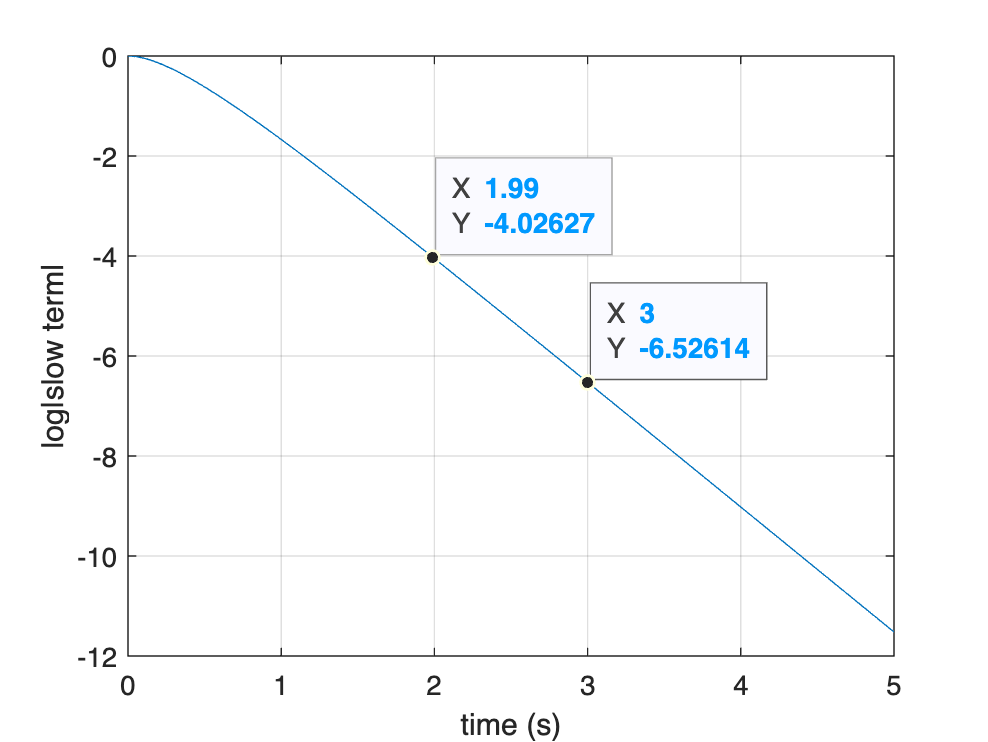

ans =   DataTip (X 3, Y -6.52614) with properties:

    DataIndex: 301
     Location: 'northeast'
       Parent: [1×1 Line]

  Show all properties

datatip(chart,3,-6.5)

The two data points shown on the plot can be used to find $\sigma_1$ and $\ln | A_1 |$.

sigma1 = (6.526 - 4.026)/(3 - 1.99)

sigma1 = 2.4752

lnA1 = -4.026 + sigma1*1.99;
A1 = -exp(lnA1)

A1 = -2.4590

If we then subtract the slow term from the data we are left with the fast term.


$$A_2 e^{-\sigma_2 t} = 1 - y(t) - A_1 e^{-\sigma_1 t}$$


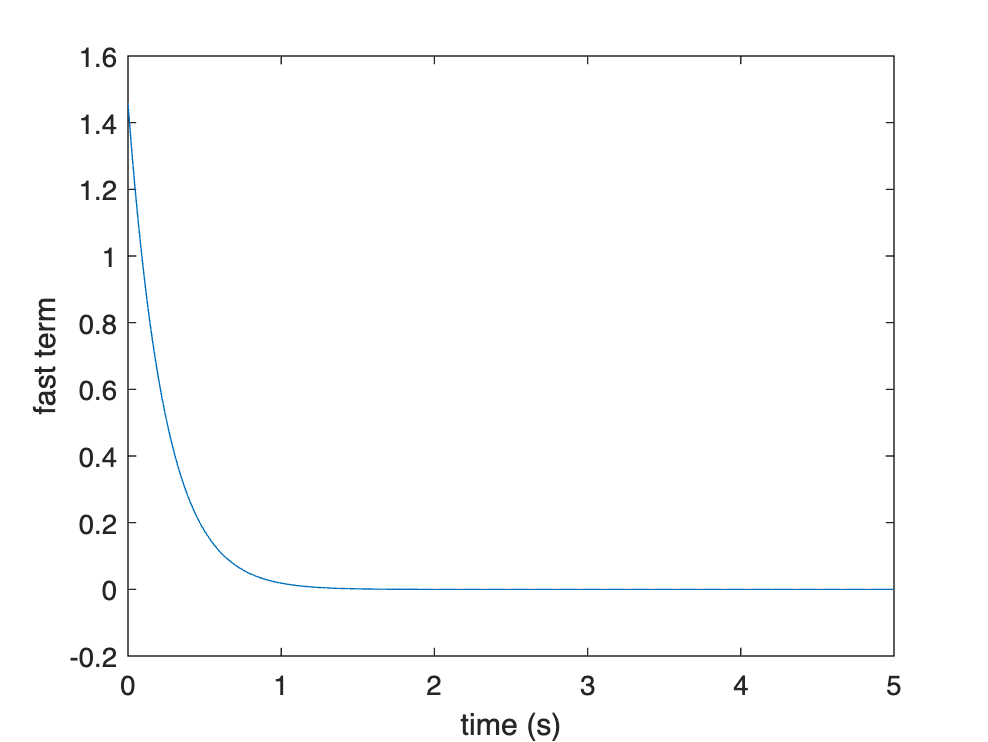

fast_term = slow_term - A1*exp(-sigma1*t);
plot(t,fast_term)
xlabel('time (s)')
ylabel('fast term')

The sign of the fast term is positive, so we know that $A_2$ is positive.  We can plot log of this we get


$$\ln | A_2 | - \sigma_2 t$$


which is a straight line.  Since this is the fast term, it is only valid over very short time periods, say less than the slow time constant $\tau_1 = 1/\sigma_1$.

plot(t,log(abs(fast_term)))
xlabel('time (s)')
ylabel('log|fast term|')
xlim([ 0 1/sigma1 ])
grid on

ax = gca;
chart = ax.Children(1);
datatip(chart,0.1,-0.05)

ans =   DataTip (X 0.1, Y -0.0406222) with properties:

    DataIndex: 11
     Location: 'northeast'
       Parent: [1×1 Line]

  Show all properties

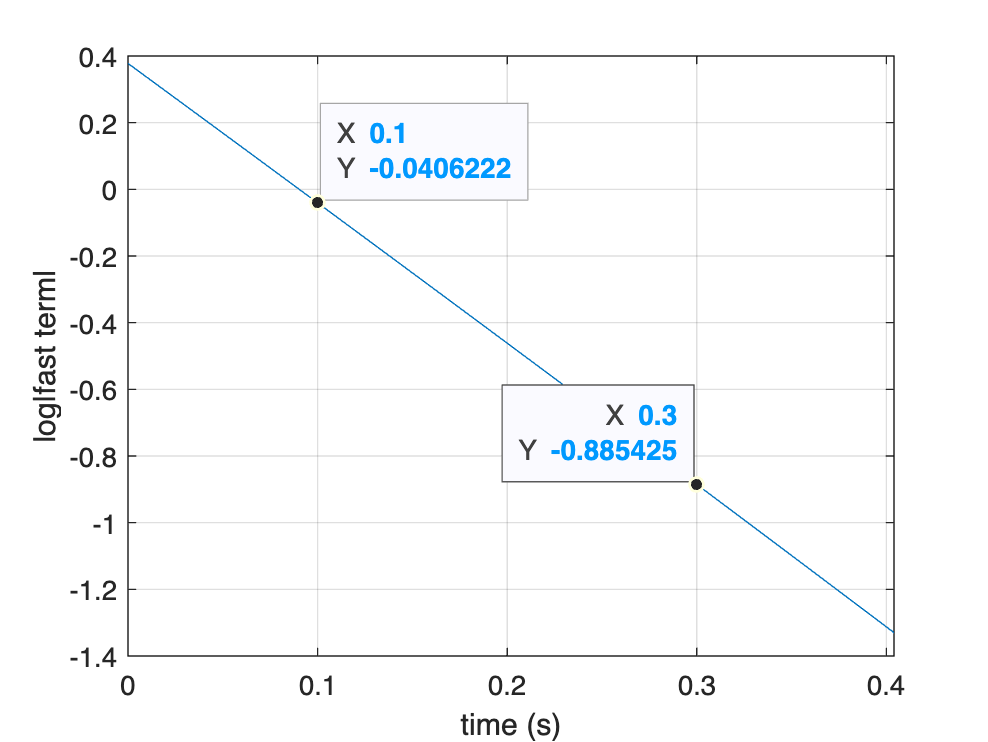

ans =   DataTip (X 0.3, Y -0.885425) with properties:

    DataIndex: 31
     Location: 'northeast'
       Parent: [1×1 Line]

  Show all properties

datatip(chart,0.3,-0.9)

The two data points shown on the plot can be used to find $\sigma_2$ and $\ln | A_2 |$.

sigma2 = (0.8854 - 0.04062)/(0.3 - 0.1)

sigma2 = 4.2239

lnA2 = -0.04062 + sigma2*0.1;
A2 = +exp(lnA2)

A2 = 1.4649

The overall fit is 

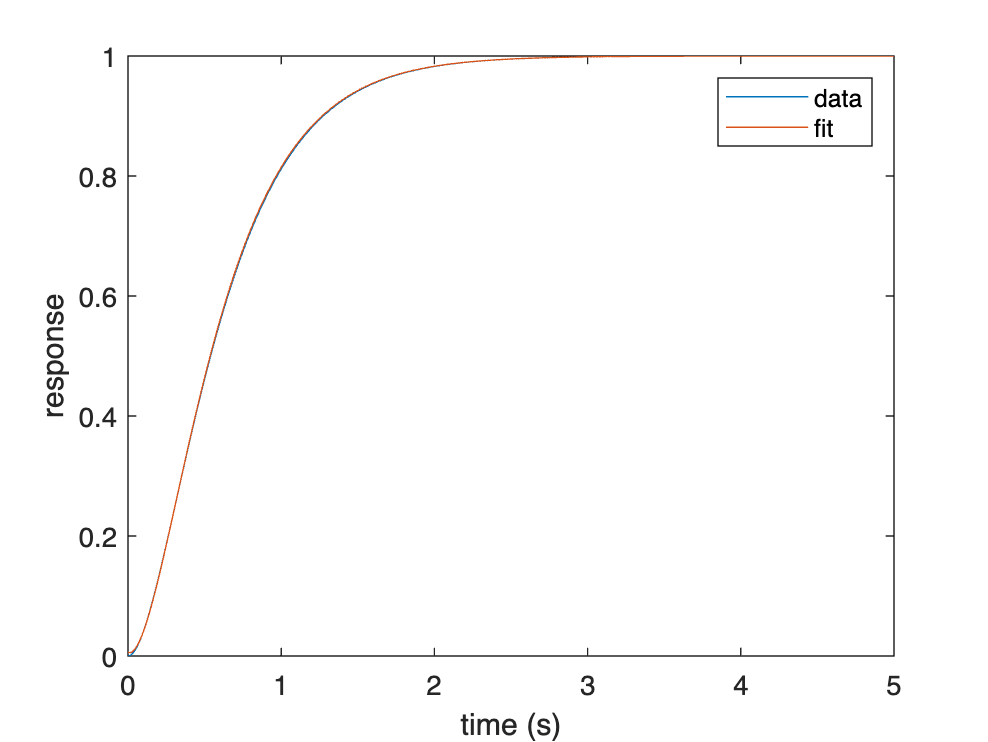

yfit = 1 + A1*exp(-sigma1*t) + A2*exp(-sigma2*t);
plot(t,y,t, ...
    yfit)
xlabel('time (s)')
ylabel('response')
legend('data','fit')

which seems to match the data well.

In the Laplace domain, the response is


$$\hat{y}(s) = \frac{1}{s} + \frac{A_1}{s + \sigma_1} + \frac{A_2}{s + \sigma_2}$$


Recall this is a step response, so


$$\hat{u}(s) = \frac{1}{s}$$


And the transfer function is


$$G(s) = 1 +  \frac{A_1s}{s + \sigma_1} + \frac{A_2s}{s + \sigma_2}$$


s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = 1 + A1*s/(s+sigma1) + A2*s/(s + sigma2)

G =
 
  0.005905 s^2 - 0.06137 s + 10.46
  --------------------------------
       s^2 + 6.699 s + 10.46
 
Continuous-time transfer function.



damp(G)

                                                           
   Pole        Damping       Frequency      Time Constant  
                           (rad/seconds)      (seconds)    
                                                           
 -2.48e+00     1.00e+00       2.48e+00         4.04e-01    
 -4.22e+00     1.00e+00       4.22e+00         2.37e-01    


This is an acceptable result and will be useful for control system design. 

The small coefficients in the numerator polynomial might mean they can be ignored.  Let's see how it compares.

G_ = 10.46/(s^2 + 6.699*s + 10.46)

G_ =
 
          10.46
  ---------------------
  s^2 + 6.699 s + 10.46
 
Continuous-time transfer function.



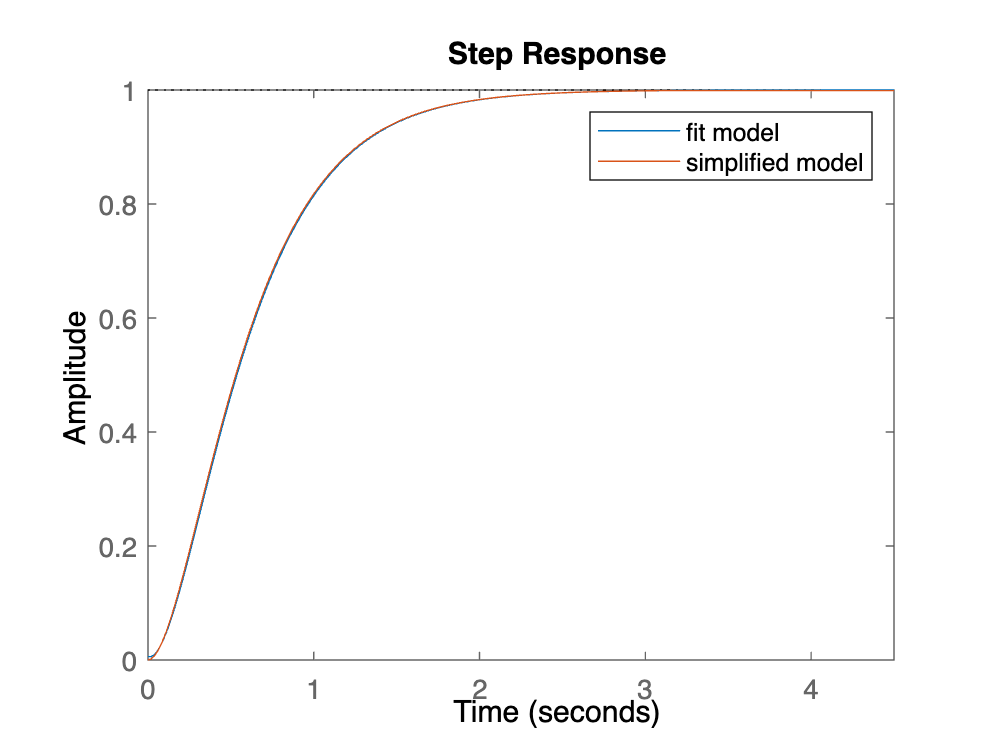

step(G,G_)
legend('fit model','simplified model')

They match, so that might be a good simplification.